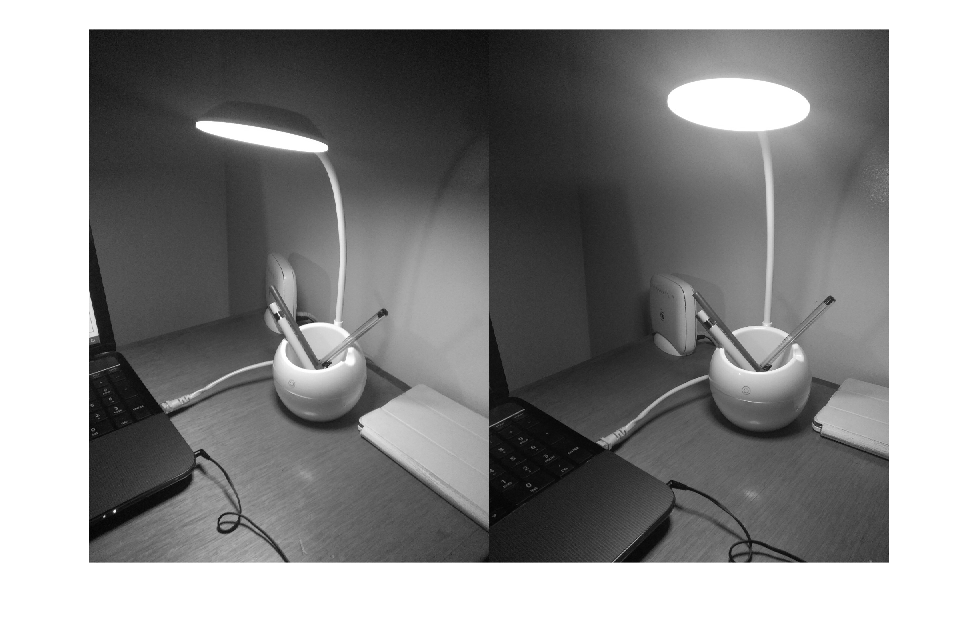

fixed  = imread('..\images\img1.jpg'); moving = imread('../images/img2.jpg');

fixed  = rgb2gray(fixed); moving = rgb2gray(moving);

imshowpair(fixed,moving,'montage')

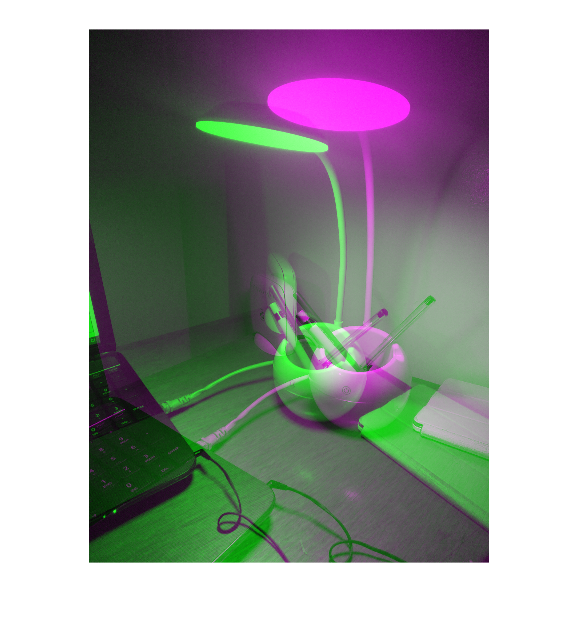


imshowpair(fixed,moving)

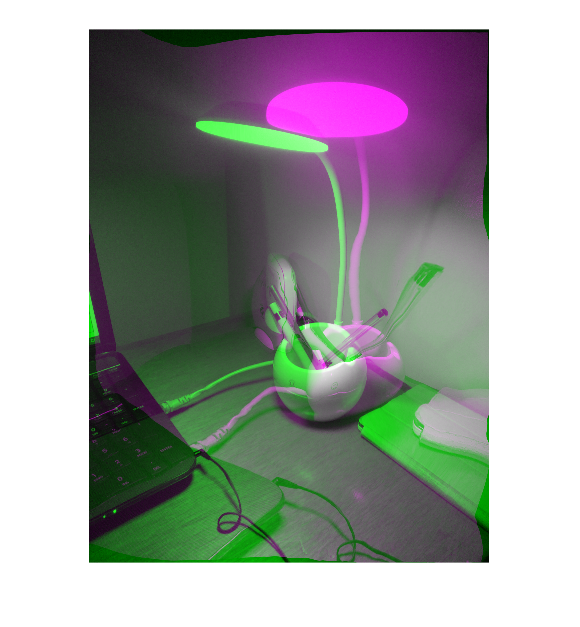


[~,movingReg] = imregdemons(moving,fixed,[500 400 200], 'AccumulatedFieldSmoothing',1.3);

moving = imhistmatch(movingReg,fixed);

imshowpair(fixed,movingReg)

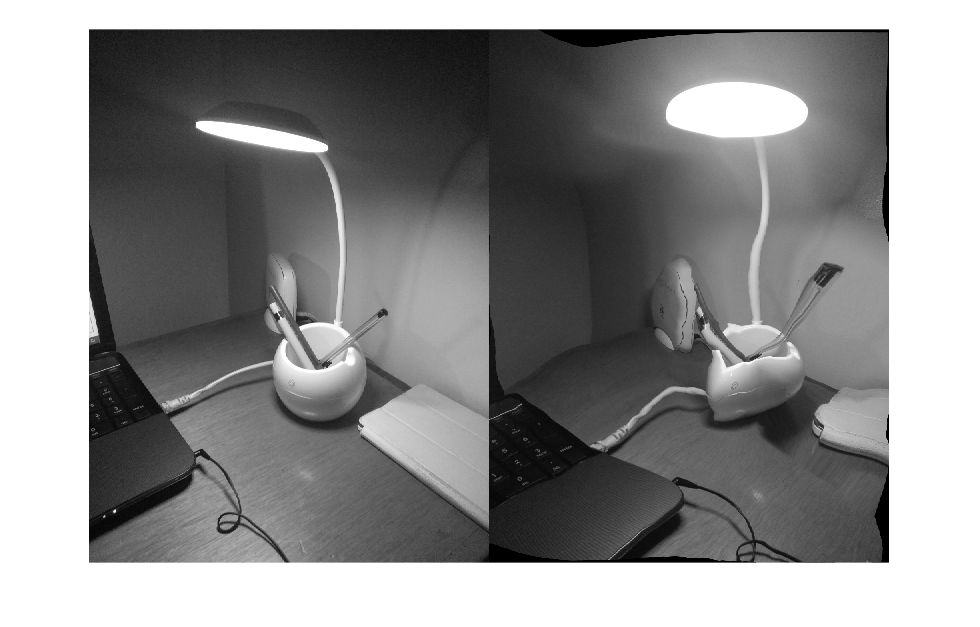


imshowpair(fixed,movingReg,'montage')

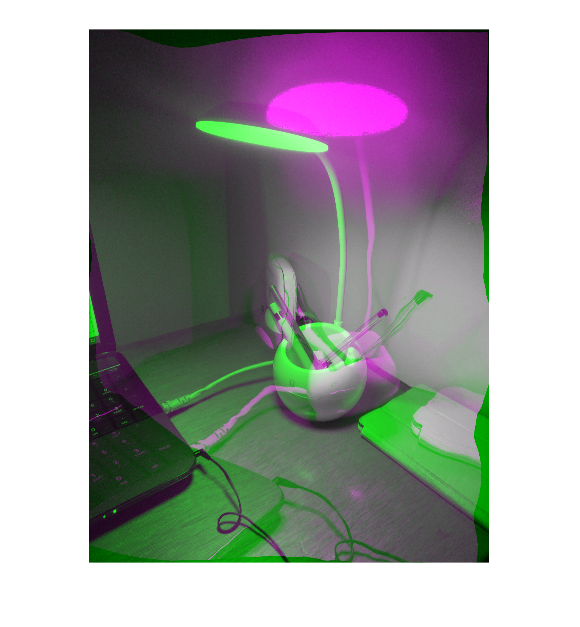

% Para unir varias imagenes prueba

primera = imread('..\images\img1.jpg');
segunda = imread('..\images\img2.jpg');
tercera = imread('..\images\img1.jpg');

%Correccion de colores
primera = rgb2gray(primera);
segunda = rgb2gray(segunda);
tercera = rgb2gray(tercera);

segunda = imhistmatch(segunda,primera);

[~,merge] = imregdemons(segunda, primera,[500 400 200], 'AccumulatedFieldSmoothing',1.3);

imshowpair(primera,merge)

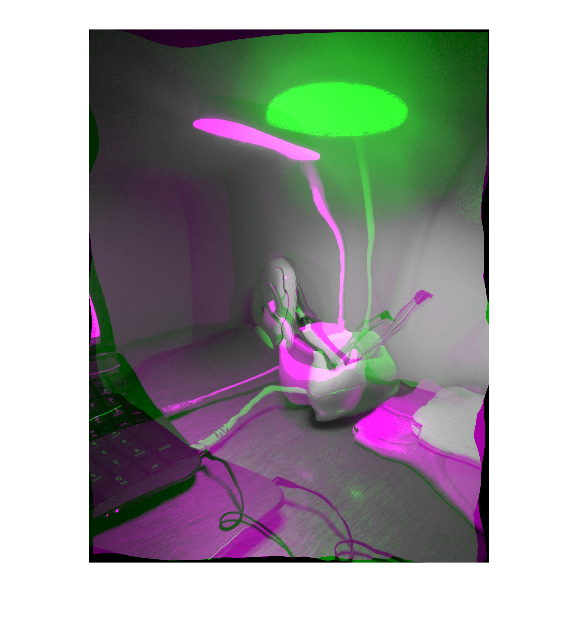


tercera = imhistmatch(tercera,merge);

[~,merge2] = imregdemons(tercera, merge,[500 400 200], 'AccumulatedFieldSmoothing',1.3);

imshowpair(merge,merge2)

% For para unir varias imagenes e insertarlas en un video
video =  VideoWriter('salida.avi');

open(video);

pri = imread('./images2/IMG_20220210_113233_BURST002.jpg');
pri = rgb2gray(pri);
pri = imresize(pri,[1600,1200]);
writeVideo(video,pri);
for i = 3:15
    seg = imread(strcat('./images2/IMG_20220210_113233_BURST00',int2str(i),'.jpg'));
    seg = imhistmatch(seg,pri);
    [~,merge] = imregdemons(segunda, primera,[500 400 200], 'AccumulatedFieldSmoothing',1.3);
    writeVideo(video,merge);
    pri = seg;
end

close(video);

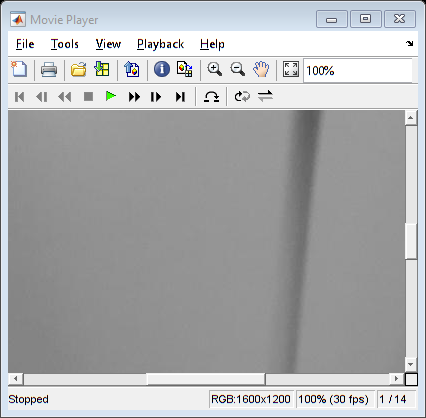

implay('salida.avi')